# Sequence-to-Sequence Classification Using 1-D Convolutions

This example shows how to classify each time step of sequence data using a generic temporal convolutional network (TCN).

PRJ: see also NN models published here: [https://paperswithcode.com/paper/eegnet-a-compact-convolutional-network-for](https://paperswithcode.com/paper/eegnet-a-compact-convolutional-network-for) 

clear all; close all;

## Loading all the data

% SrcPath = '/home/peter/Projects/EEG/NN-classification/data/eyes';
SrcPath = '../data/eyes/Combined/';
SrcNamePattern={'*_EC.mat','*_EO.mat'};
ClassNames=categorical({'EC','EO'});

channelList = {'Fp1';'AF7';'AF3';'F1';'F3';'F5';'F7';'FT7';'FC5';'FC3';'FC1';'C1';'C3';'C5';'T7';'TP7';'CP5';'CP3';'CP1';'P1';'P3';'P5';'P7';'P9';'PO7';'PO3';'O1';'Iz';'Oz';'POz';'Pz';'CPz';'Fpz'; 'Fp2';'AF8';'AF4';'Afz';'Fz';'F2';'F4';'F6';'F8';'FT8';'FC6';'FC4';'FC2';'FCz';'Cz';'C2';'C4';'C6';'T8';'TP8';'CP6';'CP4';'CP2';'P2';'P4';'P6';'P8';'P10';'PO8';'PO4';'O2'};
elToConsider = {'Cz';'C3';'C4'};
elPositions = find(ismember(channelList, elToConsider)); % this may not always be used, but that's not a problem
srate = 256; % sampling frequency in Hz

files=cell(numel(SrcNamePattern),1);
for npat=1:numel(SrcNamePattern)
    files{npat} = dir([ SrcPath filesep SrcNamePattern{npat}]); 
    for nfile=1:numel(files{npat})
        files{npat}(nfile).data=load( ...
            [ files{npat}(nfile).folder filesep ...
              files{npat}(nfile).name ]).dataRest(elPositions,:);
        files{npat}(nfile).class=ClassNames(npat);
    end
end
files = vertcat(files{:}); % flatten to have all files together

Data organization and splitting into training/validation/testing:

Inputs = {};
Outputs = {};
nClasses = numel(categories(ClassNames));
chunkSize = 4*srate; % 4 seconds;

for nfile = 1:numel(files)
    nChunks=floor(size(files(nfile).data,2)/chunkSize);
    for i=1:nChunks
        Inputs{end+1}=files(nfile).data(:,((i-1)*chunkSize+1):(i*chunkSize));
        Outputs{end+1}=repmat(files(nfile).class,[1,chunkSize]);
    end
end


Divide data randomly into **train**, **test** and **validation** datasets

%PRJ - todo: load all data first and then divide it using 'dividerand' to
%define train, test and validation datasets
nChunks=numel(Outputs);
[trainInd,valInd,testInd] = dividerand(nChunks,0.8,0,0.2); % remove validation proportion
 
InTrain = Inputs(1,trainInd);
OutTrain= Outputs(1,trainInd);
% InValid = Inputs(1,valInd);
% OutValid= Outputs(1,valInd);
InTest  = Inputs(1,testInd);
OutTest= Outputs(1,testInd);


Adopt the network to the **Seq-to-Label**:

OutTrain = SeqToLabel(OutTrain);
% OutValid = SeqToLabel(OutValid);
OutTest = SeqToLabel(OutTest);

## Define Deep Learning Model

layers = [
    sequenceInputLayer(3,"Name","input")
    lstmLayer(128,"Name","lstm","OutputMode","last")
    dropoutLayer(0.5,"Name","dropout")
    fullyConnectedLayer(2,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classification")];

lgraph = layerGraph(layers);

View the network in a plot.

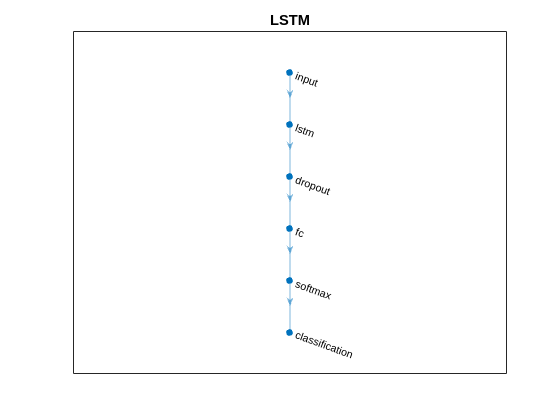

figure
plot(lgraph)
title("LSTM")

## Specify Training Options

Specify a set of options used for training.

- Train for 60 epochs with a mini-batch size of 1.

- Train with a learning rate of 0.001.

- Display the training progress in a plot and suppress the verbose output.

options = trainingOptions("adam", ...
    MaxEpochs=500, ...
    miniBatchSize=50, ...
    Plots="training-progress", ...
    Verbose=true);

% options = trainingOptions("adam", ...
%     MaxEpochs=500, ...
%     miniBatchSize=50, ...
%     ValidationData={InValid,OutValid}, ...
%     ValidationFrequency=100, ...
%     Plots="training-progress", ...
%     Verbose=true);

## Train Model

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       48.00% |       0.8365 |          0.0010 |
|       5 |          50 |       00:00:05 |       38.00% |       0.9030 |          0.0010 |
|      10 |         100 |       00:00:08 |       72.00% |       0.5512 |          0.0010 |
|      14 |         150 |       00:00:10 |       72.00% |       0.5762 |          0.0010 |
|      19 |         200 |       00:00:13 |       48.00% |       0.7406 |          0.0010 |
|      23 |         250 |       00:00:15 |       48.00% |       0.6766 |          0.0010 |
|      28 |         300 |       00:00:17 |       48.00% |       0.

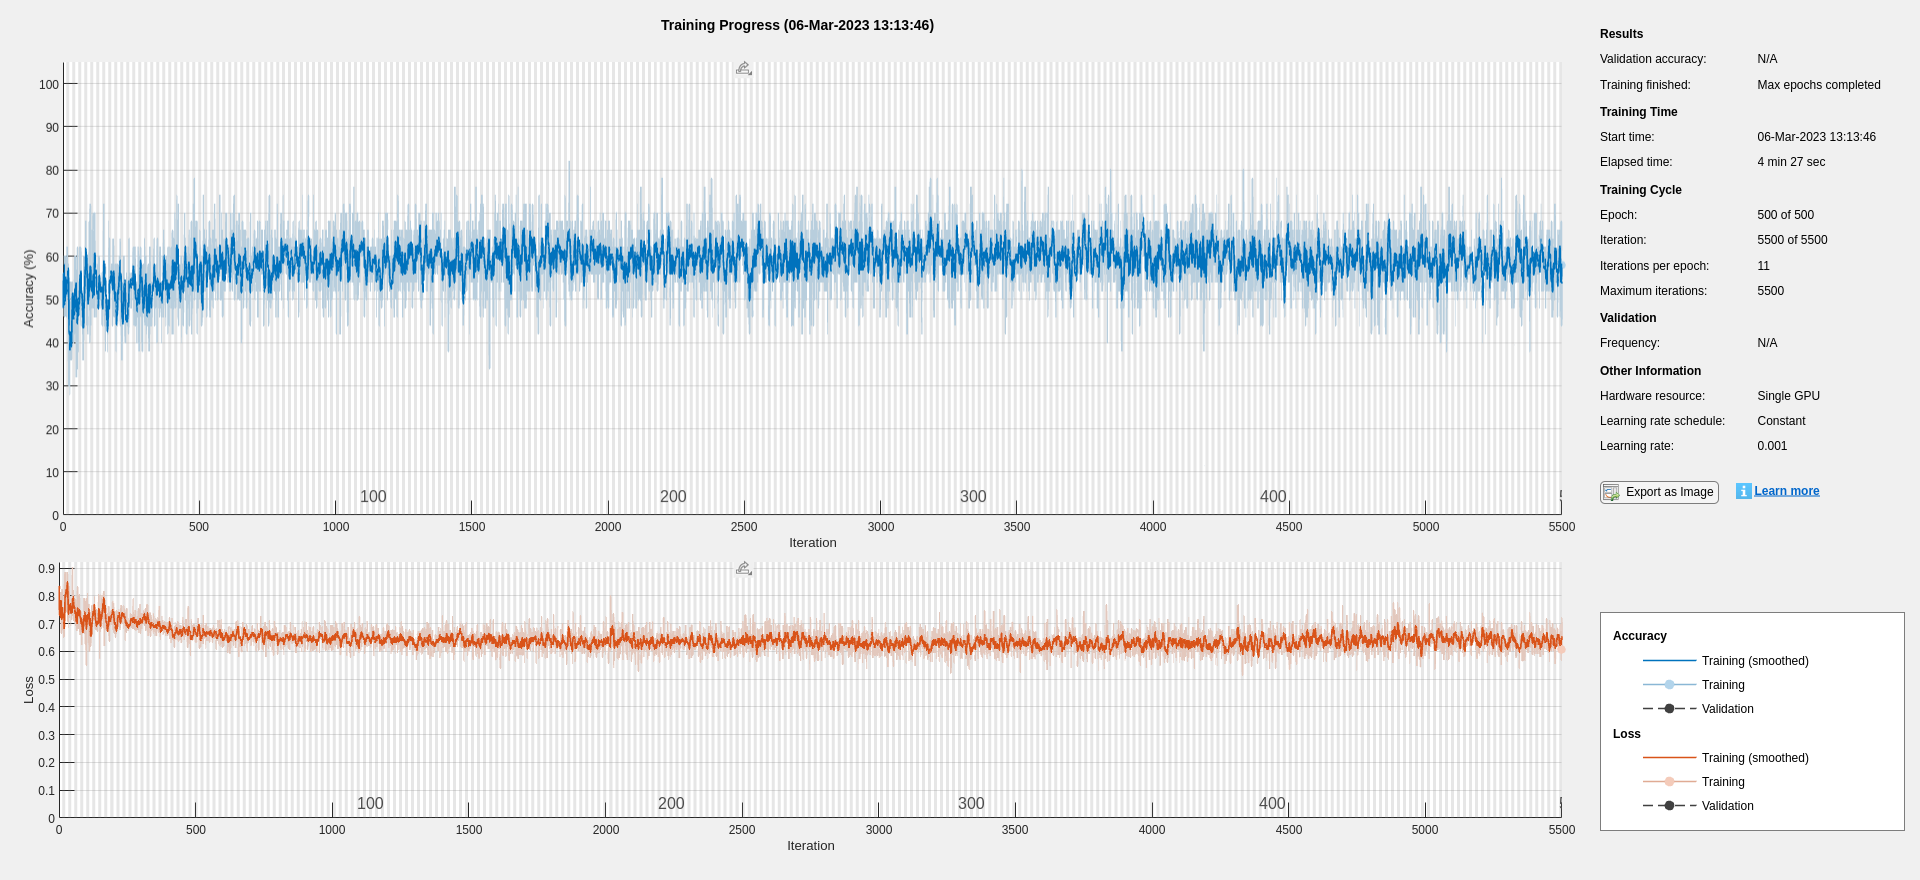

net = trainNetwork(InTrain,OutTrain,lgraph,options);

## Train more

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       66.00% |       0.6537 |          0.0010 |
|       5 |          50 |       00:00:03 |       52.00% |       0.8354 |          0.0010 |
|      10 |         100 |       00:00:06 |       58.00% |       0.7873 |          0.0010 |
|      14 |         150 |       00:00:08 |       48.00% |       0.9259 |          0.0010 |
|      19 |         200 |       00:00:10 |       42.00% |       1.0152 |          0.0010 |
|      23 |         250 |       00:00:13 |       48.00% |       0.8175 |          0.0010 |
|      28 |         300 |       00:00:15 |       58.00% |       0.

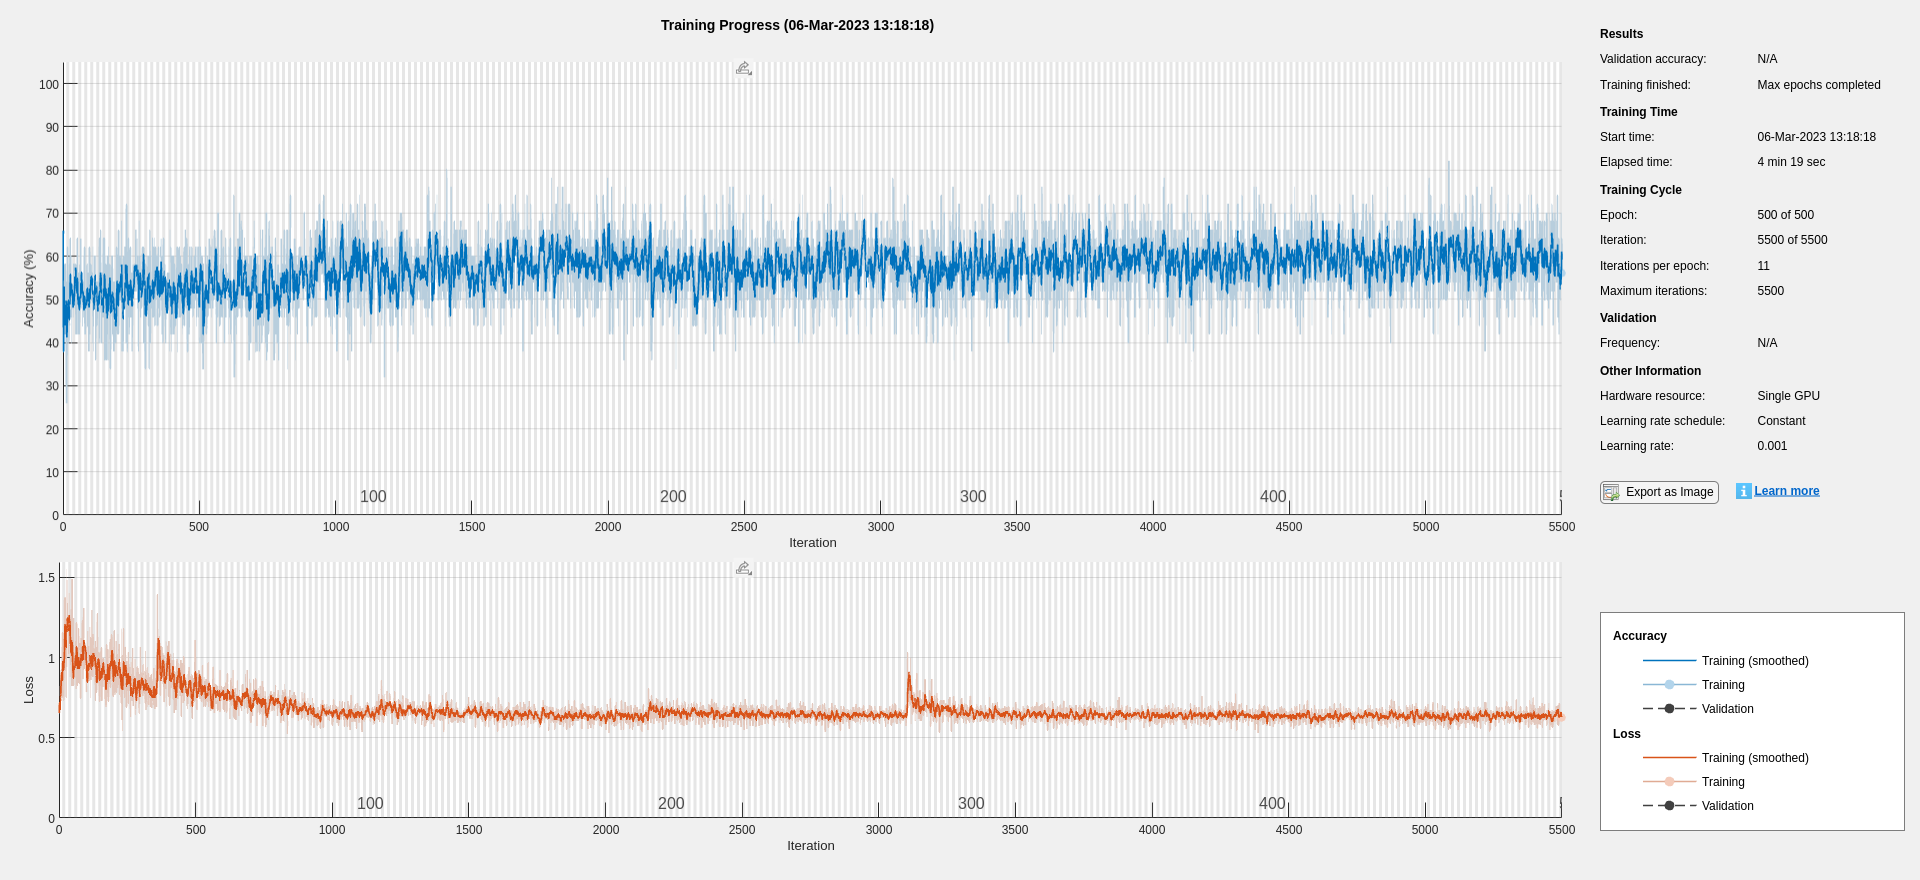

net = trainNetwork(InTrain,OutTrain,layerGraph(net),options);

save('net1.mat',"net");

## Test Model

Test the classification accuracy of the model by comparing the predictions on a held-out test set with the true labels for each time step. 

Use the trained network to make predictions by using the `classify` function.

OutPred = classify(net,InTest);

Visualize the predictions for **each sample** in a confusion matrix.

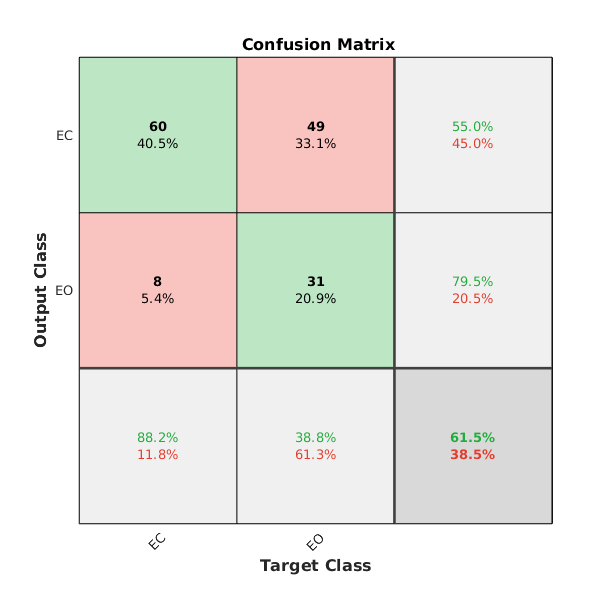

Pred = OutPred;
True = OutTest;
plotconfusion(True(:),Pred(:));

Visualize the predictions for **each sample** in a confusion matrix.

% Pred = vertcat(OutPred{:});
% True = vertcat(OutTest{:});
% PredCount = countcats(Pred');
% Predictions=1*(PredCount(1,:)<PredCount(2,:));
% PredChunk = categorical(Predictions,[0 1],{'EC', 'EO'});
% TrueChunk = True(:,1);
% plotconfusion(TrueChunk(:),PredChunk(:));